clear all

prob_map_img = imread('prob_map.png');
prob_map = prob_map_img(:,:,1);

[max_x,max_y] = size(prob_map)

max_x = 20

max_y = 20


[x, y] = meshgrid(1:max_x, 1:max_y);
x = reshape(x,max_x^2,1);
y = reshape(y,max_y^2,1);

pos = [max_x/2 0.1+max_y/2];
r = 2.5;

L = linspace(0,2*pi,360);
% circle = [pos(1)+r*cos(L); pos(2)+r*sin(L)]';
circle = polyshape(pos(1)+r*cos(L),pos(2)+r*sin(L));


area_covered = zeros(length(x),1);
tic
for i = 1:length(x)
    c1 = [x(i),y(i)];
    c2 = [x(i)+1,y(i)];
    c3 = [x(i),y(i)+1];
    c4 = [x(i)+1,y(i)+1];
    
    dc1 = norm(pos - c1);
    dc2 = norm(pos - c2);
    dc3 = norm(pos - c3);
    dc4 = norm(pos - c4);
    
    dists = [dc1 dc2 dc3 dc4]<r;
    
    if all(dists)
        area_covered(i) = 1;
    elseif any(dists)
        poly = [c1; c2; c4; c3; c1];
        poly = polyshape(poly(:,1), poly(:,2));
        polyout = intersect(poly,circle);
        area_covered(i) = polyout.area;
    end
end
toc

Elapsed time is 0.115390 seconds.


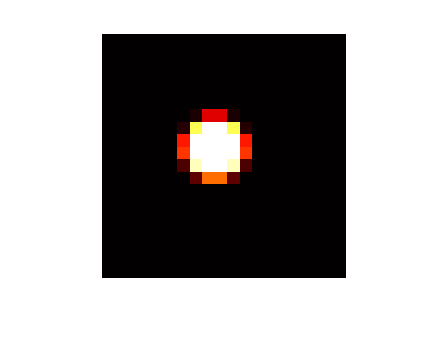


area_covered = reshape(area_covered,max_x,max_y);

imshow(area_covered), colormap hot
hold on
xlim([0 max_x])
ylim([0 max_y])


disp(pos)

   10.0000   10.1000


disp(sum(cast(prob_map,'double').*area_covered,'all'))

   2.2012e+03
